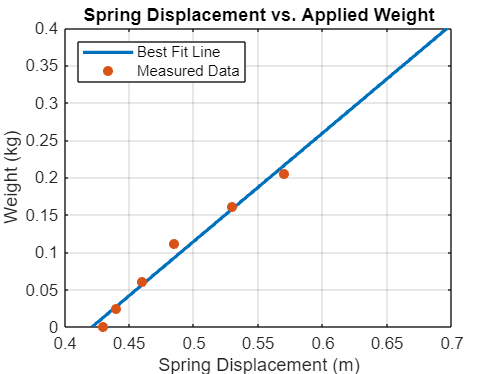

clear; 
weights = [0, 25, 61, 112, 161, 206]/1000; % g to kg
stretches = ([49, 50, 52, 54.5, 59, 63]-6)/100; % cm to m
num_trials = size(weights, 2);

forces = weights * 9.81; % kg to N

A = [stretches', ones(num_trials, 1)];
Y = forces';

params = (A' * A) \ (A' * Y); % Linear regression
stiffness = params(1); % spring constant k
l_0 = -params(2) / stiffness;




% Generate values for plotting
mass_vals = 0:0.001:0.4;  % kg
force_vals = mass_vals * 9.8;  % N
lengths = l_0 + (force_vals / stiffness);

figure
plot(lengths, mass_vals, 'LineWidth', 2)
hold on
scatter(stretches, weights, 'filled')
hold off

title('Spring Displacement vs. Applied Weight')
xlabel('Spring Displacement (m)')
ylabel('Weight (kg)')
legend('Best Fit Line', 'Measured Data', 'Location', 'northwest')
grid on

% compute natural frequency
cart_mass = 0.748; % kg
natural_freq = sqrt(stiffness/cart_mass);
